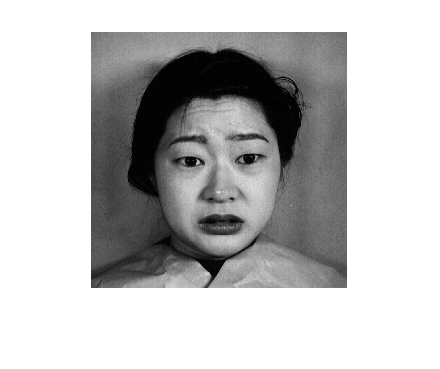

img_folder='../../PCA_Dataset/';
img_file=dir(fullfile(img_folder,'*.*'));
num_images=length(img_file);
random_index=randi(num_images);
random_image_name=fullfile(img_folder,img_file(random_index).name);
random_img=imread(random_image_name);
% imshow(random_img);
% gray_img=double(rgb2gray(random_img));
random_img=double(random_img);


mean_img=mean(random_img(:));
std_img=std(random_img(:));
random_img=(random_img-mean_img)/std_img;


[u,s,v]=mysvd(random_img);

%num of components for change and see another result
num_of_components=5;


recon_img=u(:,1:num_of_components) * s(1:num_of_components,1:num_of_components) * v(:,1:num_of_components)' ;

% diff
imshow(uint8(random_img*std_img +mean_img));

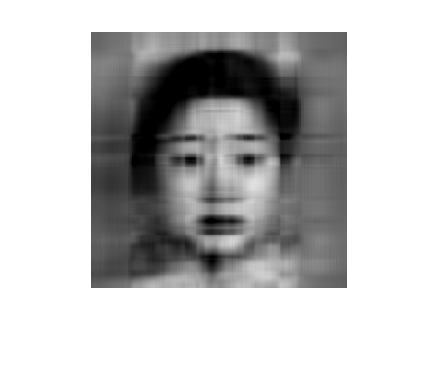

imshow(uint8(recon_img * std_img + mean_img));

[m, n]=size(random_img);
original_size=m*n;
compressed_size=num_of_components*(m+n+1);

disp(['diff of 2 picure %', num2str(100* (1-compressed_size/original_size))]);

diff of 2 picure %96.0861
